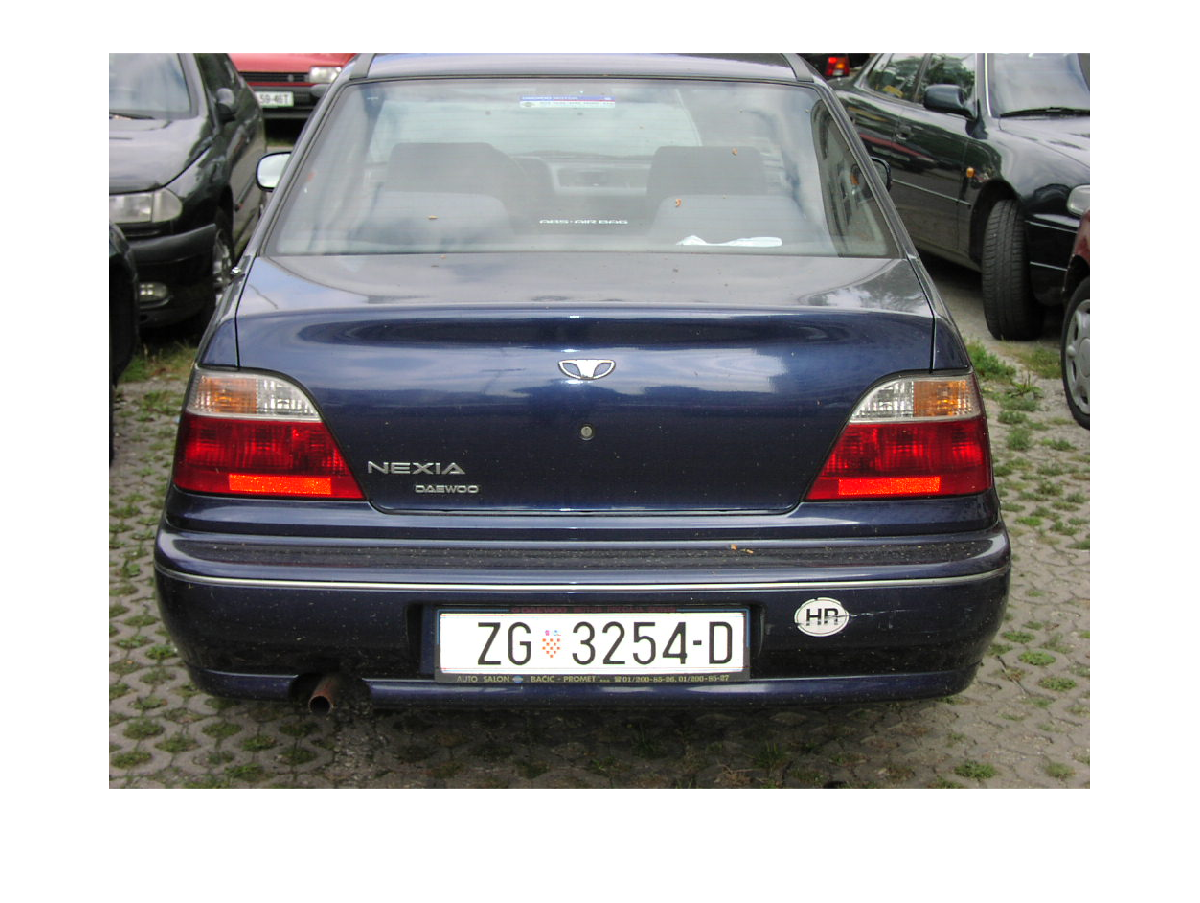

% Read in the image
img = imread('test_images\image_2.JPG');
img_copy = img;
% Get the size of the image 
% (number of rows = hight, columns = width, and channels)
[h,w,f]=size(img);
% Display the original image
imshow(img);

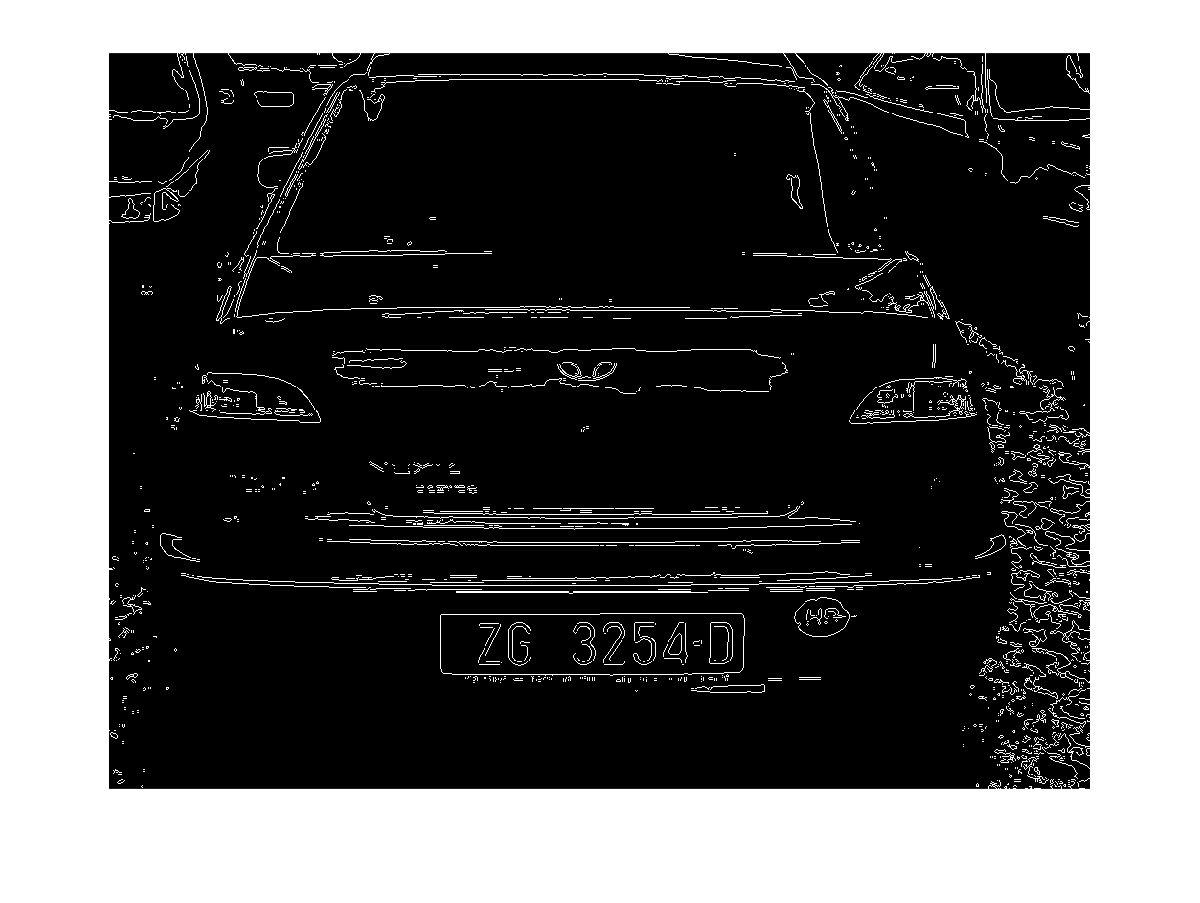

% Apply OTSU method: first, convert the image to grayscale to be 
% able to do a threshold on the binary image (everything below 
% the threshold is 1, everything above becomes 0)
img = rgb2gray(img);
% Then, get OTSU theshold
level = graythresh(img);
% Apply the threshold with 30% more to get a better result
img = im2bw(img,level*1.3);
% For edge detection, we use a built-in matlab function for it
% (edge) with the prewitt filter or kernal
img = edge(img,'prewitt');
imshow(img);

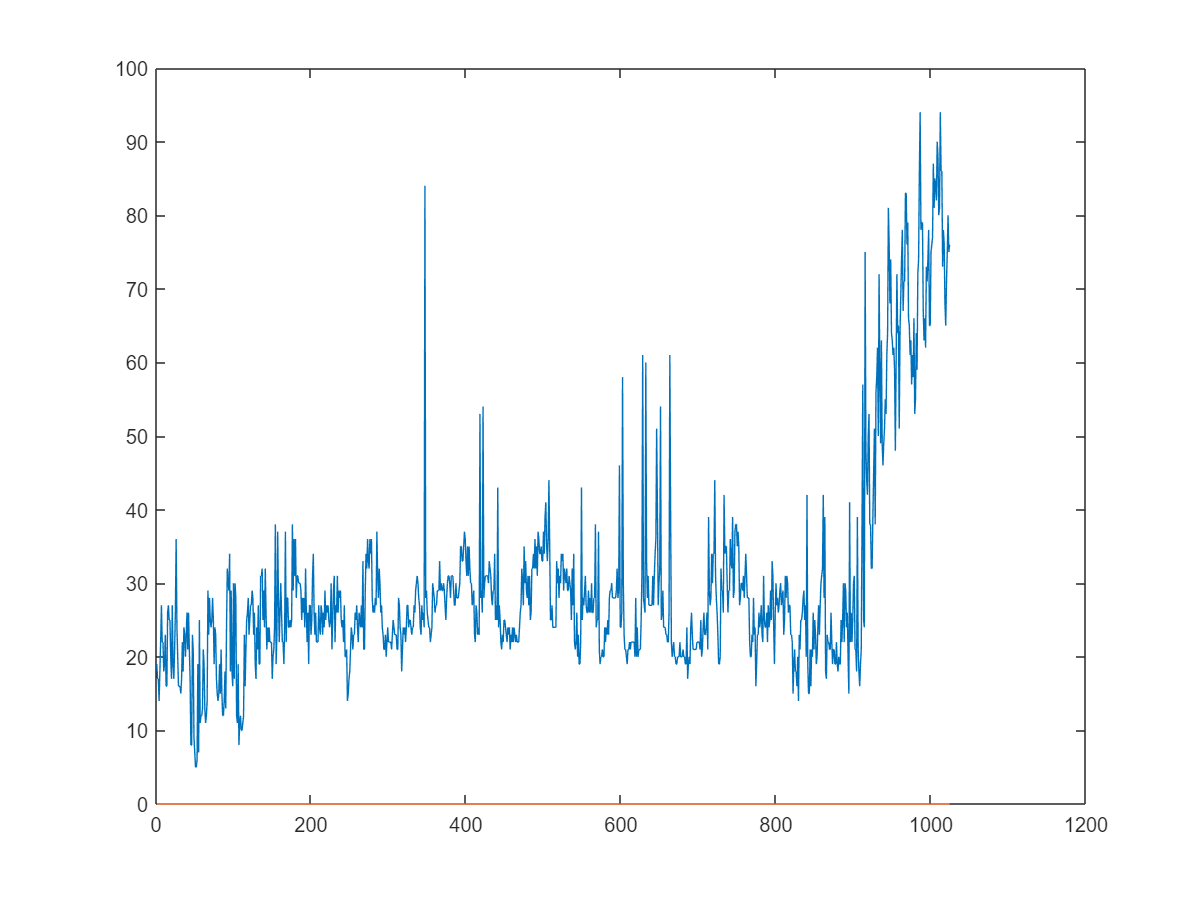

% Create vector with the same size as the columns (width) of the image
horizontal_Histogram = zeros(w);
% The number of white pixels per column are added and stored
for i = 1:w
    total = 0;
    for j = 1:h
        if (img(j,i) == 1)
            total = total+1;
        end
    end
    horizontal_Histogram(i) = total;
end
% calculated threshold
average = max(horizontal_Histogram)/2.3;
plot(horizontal_Histogram);

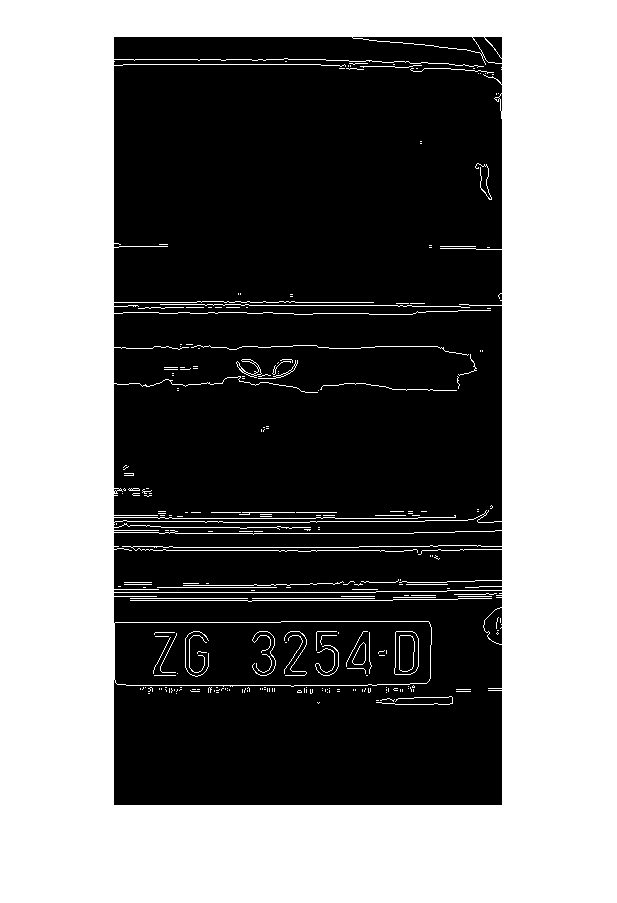

hstart = 0;
width = 0;
hcounter = 0;
arc = 0;
hcoor = zeros(1,2);
%if the number of white pixels for a certain distance (defined in percentages) is greater than the
%threshold, this position is stored as the horizontal position of the
%license plate
for i = 1:w
    if horizontal_Histogram(i) > average(1)
        if hstart == 0
            hstart = i;
        end
        hcounter = 0;
    else
        if hstart > 0
            if hcounter > (w*0.07)
                heinde = i - hcounter;
                width = heinde - hstart;
                if(width > (w*0.1))
                    arc = arc+1;
                    hcoor(arc,1) = hstart;
                    hcoor(arc,2) = width;
                end
                hstart = 0;
                hcounter = 0;
                heinde = 0;
                width = 0;
            end
            hcounter = hcounter+1;
        end
    end
end
[ww,f] = size(hcoor);
hstart = 0;
hwidth = 0;
% in case multiple horizontal places are found for the
% number plate then we only pick out the widest position.
for i = 1:ww
    if(hcoor(i,2) > hwidth)
        hwidth = hcoor(i,2);
        hstart = hcoor(i,1);
    end
end
img = img(:,hstart:(hstart+hwidth),:);
imshow(img);

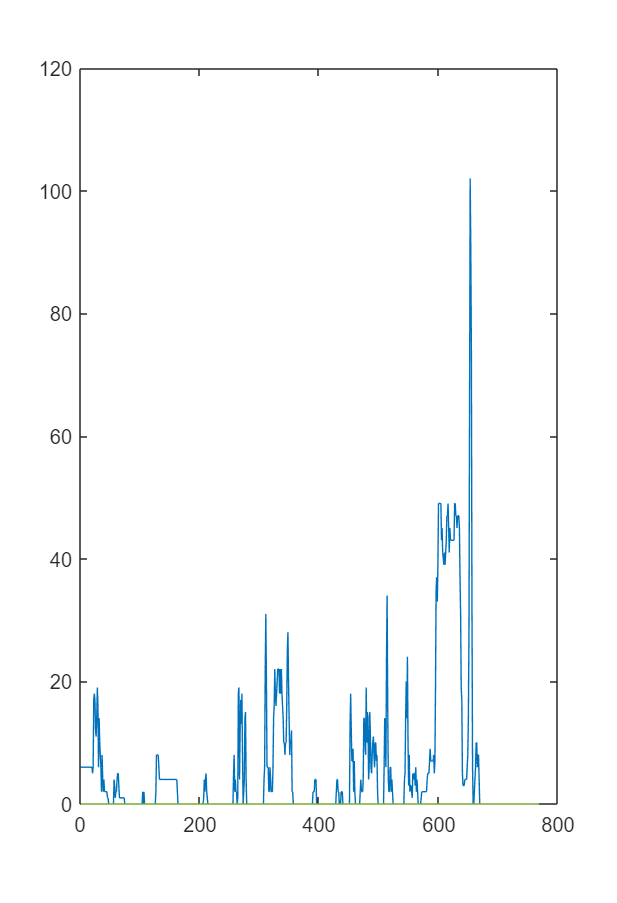

verHist=zeros(h);
%the number of times a pixel and its neighbor in a row are opposite
%are of each other is stored for that row.
for j = 1:h
    total = 0;
    for i = 2:hwidth
        if (img(j,i-1) == 1 && img(j,i) == 0) || (img(j,i-1) == 0 && img(j,i) == 1) 
            total = total + 1;
        end
    end
    verHist(j) = total;
end
verh = zeros(1);
coun = 1;

%we calculate the average value of the number of opposites
%neighboring pixels in a row, we use that average as a threshold later
for i = 1:h
    if(verHist(i) > 0)
        verh(coun) = verHist(i);
        coun = coun+1;
    end
end

average = mean(verh);
plot(verHist);

vstart = 0;
veinde = 0;
height = 0;
vcounter = 0;
arc = 0;
vcoor = zeros(1,2);
h*0.07

ans = 53.7600

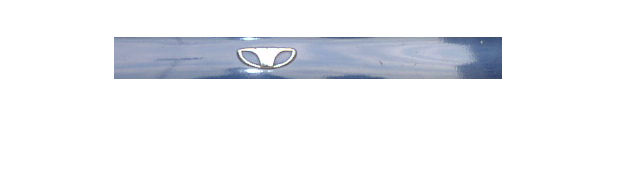

%as the number of opposite neighboring pixels per row during a
%certain width is greater than the average and then of a
%certain height is relative to the dimensions of the image, then it becomes
%position stored as possible vertical license plate location
for i = 1:h
    if verHist(i) > average(1)
        if vstart == 0
            vstart = i;
        end
        vcounter = 0;
    else
        if vstart > 0
            if vcounter > (h*0.03)
                veinde = i-vcounter;
                height = veinde-vstart;
                if height > (h*0.05)
                    arc = arc+1;
                    vcoor(arc,1) = vstart;
                    vcoor(arc,2) = height;
                end
                vstart = 0;
                vcounter = 0;
                veinde = 0;
                height = 0;
            end
            vcounter = vcounter+1;
        end
    end
end
[l,f] = size(vcoor);
%now that we have calculated the different possible positions we can
%proceed to the segmentation
img = img_copy(vcoor(1,1):vcoor(1,1)+vcoor(1,2),hstart:(hstart+hwidth),:);
imshow(img);

% finally, the characters on the license plate are segmented and recognized
tic
plate_num_1(img);

toc
tic
plate_num_2(img);

The plate number is 


toc